# GQ 2 Modèle DCC et Granger Test

clc;
clear,
data = readtable('inefficiency.xlsx');
dates = data(:,1); % date
data = data(:,2:end); % inefficiency

varNames = data.Properties.VariableNames;

### Test d'augmented Dickey Fuller

adfResults = performADFTest(data, 9)

## Test de présence d'effet ARCH

archResults = performARCHTest(data, 12)

## Etude de DCC

R = [data.s_p500 data.ssec];

adfResults = 4×4 table
    MarketIndex    ADFStatistic    LagOrder     pValue  
    ___________    ____________    ________    _________

     "s_p500"        -1.5493          9          0.11446
     "ssec"          -3.1599          9        0.0021295
     "ftse100"       -1.9659          9         0.047301
     "ftsemib"       -1.8966          9         0.055321



% Dynamic conditional model without asymmetry effect
M=1;

archResults = 4×4 table
    MarketIndex    Chisquared    df    pValue
    ___________    __________    __    ______

     "s_p500"        516.02      12      0   
     "ssec"           505.4      12      0   
     "ftse100"       514.85      12      0   
     "ftsemib"          515      12      0   


L=0;
N=1;
P=1;
O=0; % Mettre à 1 si présence d'un effet d'asymétrie
Q=1;

R =     0.0425    0.0012
    0.0597   -0.0002
    0.0611   -0.0034
    0.0689   -0.0070
    0.0839   -0.0079
    0.0785   -0.0032
    0.0866    0.0089
    0.0956    0.0123
    0.0990    0.0223
    0.1070    0.0287



% estimation of scalar DCC
[Paramdcc,LLdcc,Htdcc,VCVdcc]=dcc(R,[],M,L,N,P,O,Q);

% covariance
cov_dcc = squeeze(Htdcc(1,2,:));
v_1 = squeeze(Htdcc(1,1,:));
v_2 = squeeze(Htdcc(2,2,:));
corr_dcc = cov_dcc./sqrt(v_1.*v_2);
subplot(2,1,1);
plot(cov_dcc);
title('Covariance du modèle dcc entre ');


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.314745e+03    0.000e+00    1.097e+03
    1       7    1.074803e+03    0.000e+00    9.265e+03    6.265e-01
    2      10    1.030109e+03    0.000e+00    8.403e+01    5.826e-01
    3    

subplot(2,1,2);
plot(corr_rm_Cns)
title('Correlation entre rm et Cnsmr')


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.314745e+03    0.000e+00    1.097e+03
    1       7    1.074803e+03    0.000e+00    9.265e+03    6.265e-01
    2      10    1.030109e+03    0.000e+00    8.403e+01    5.826e-01
    3    

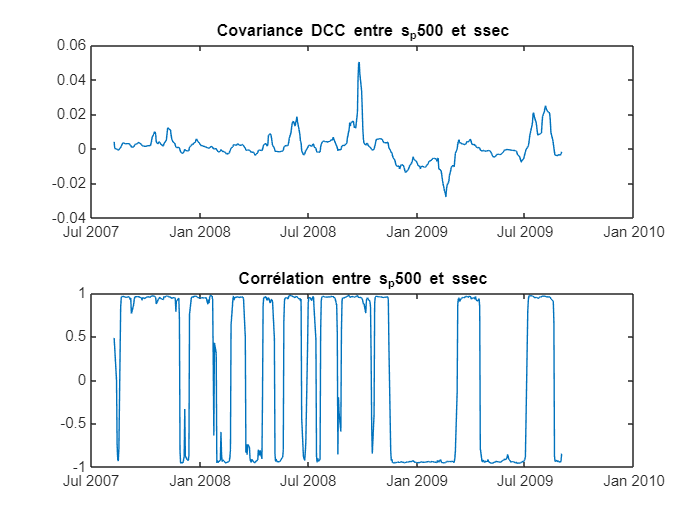


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    9.086310e+02    0.000e+00    3.803e+03
    1       9    8.199678e+02    0.000e+00    1.118e+04    1.689e-02
    2      16    9.999387e+02    0.000e+00    1.313e+03    2.041e-02
    3    

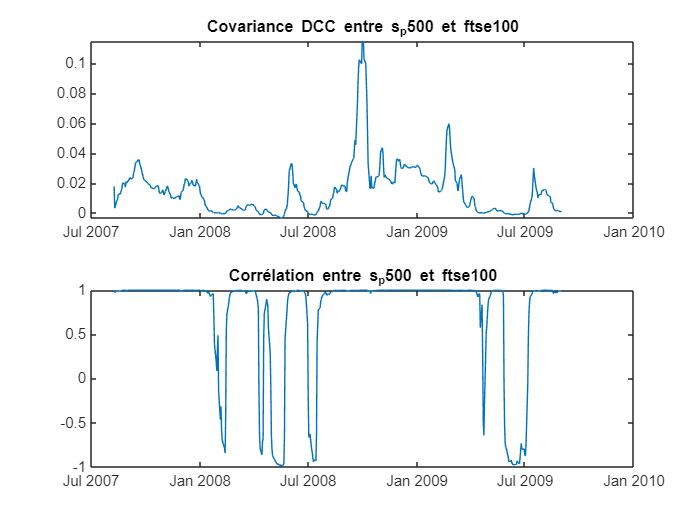


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.005546e+03    0.000e+00    3.932e+03
    1       9    9.084078e+02    0.000e+00    1.067e+04    2.018e-02
    2      16    1.110022e+03    0.000e+00    1.317e+03    2.409e-02
    3    

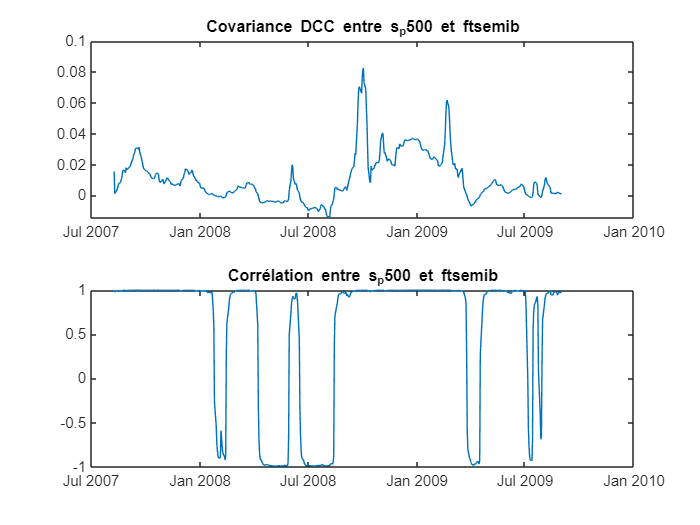


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.323918e+03    0.000e+00    8.399e+02
    1       6    1.207020e+03    0.000e+00    5.833e+02    1.076e+00
    2       9    1.164321e+03    0.000e+00    6.526e+02    7.058e-02
    3    

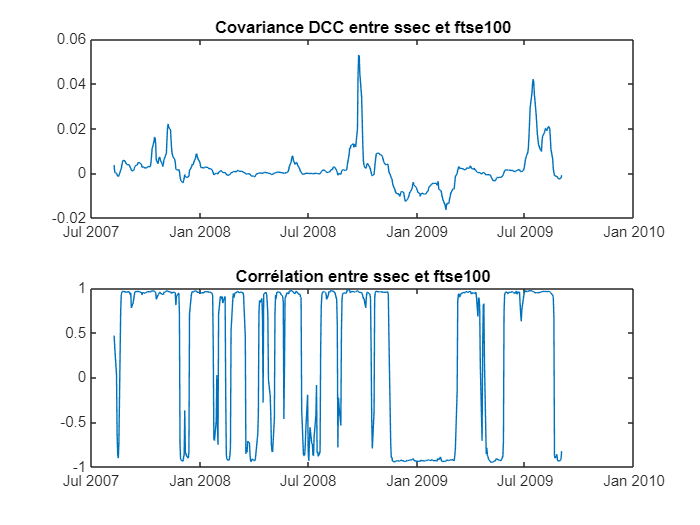


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.299794e+03    0.000e+00    1.305e+03
    1       7    1.087636e+03    0.000e+00    7.370e+03    6.265e-01
    2      10    1.058810e+03    0.000e+00    4.083e+02    5.803e-01
    3    

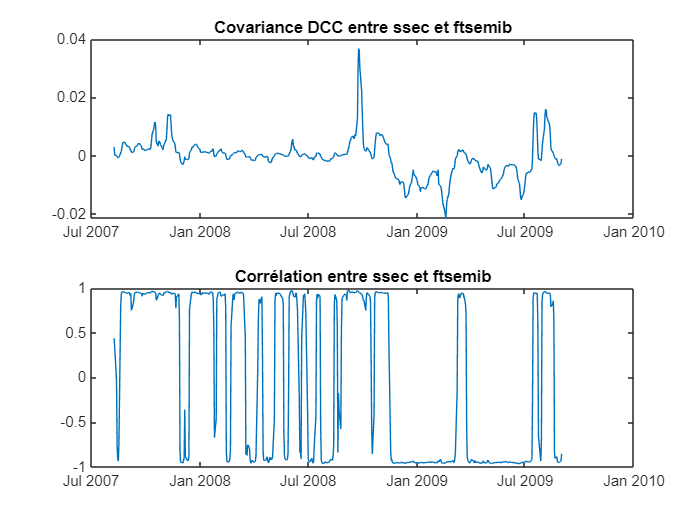


____________________________________________________________
   Diagnostic Information

Number of variables: 2

Functions 
Objective:                            dcc_likelihood
Gradient:                             finite-differencing
Hessian:                              bfgs

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    1
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          2

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.027054e+03    0.000e+00    3.428e+03
    1       9    9.452820e+02    0.000e+00    1.086e+04    1.720e-02
    2      16    1.111327e+03    0.000e+00    1.180e+03    2.072e-02
    3    

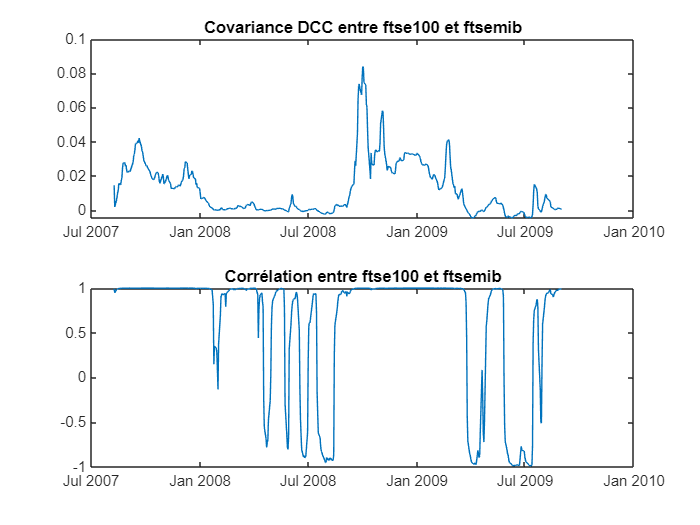

% Paramètres du modèle DCC
M = 1;
L = 0;
N = 1;
P = 1;
O = 0; % Mettre à 1 si présence d'un effet d'asymétrie
Q = 1;

for i = 1:numCols
    for j = i+1:numCols
        % Extract the pair of columns as vectors
        data1 = table2array(data(:, i));
        data2 = table2array(data(:, j));
        
        colName1 = data.Properties.VariableNames{i};
        colName2 = data.Properties.VariableNames{j};

        % Compute DCC
        [cov_dcc, corr_dcc] = computeDCC(data1, data2, M, L, N, P, O, Q);

        % Create a new figure for each pair
        figure;

        % Plot the results
        subplot(2, 1, 1);
        plot(table2array(dates), cov_dcc);
        title(['Covariance DCC entre ', colName1, ' et ', colName2]);

        subplot(2, 1, 2);
        plot(table2array(dates), corr_dcc);
        title(['Corrélation entre ', colName1, ' et ', colName2]);
    end
end